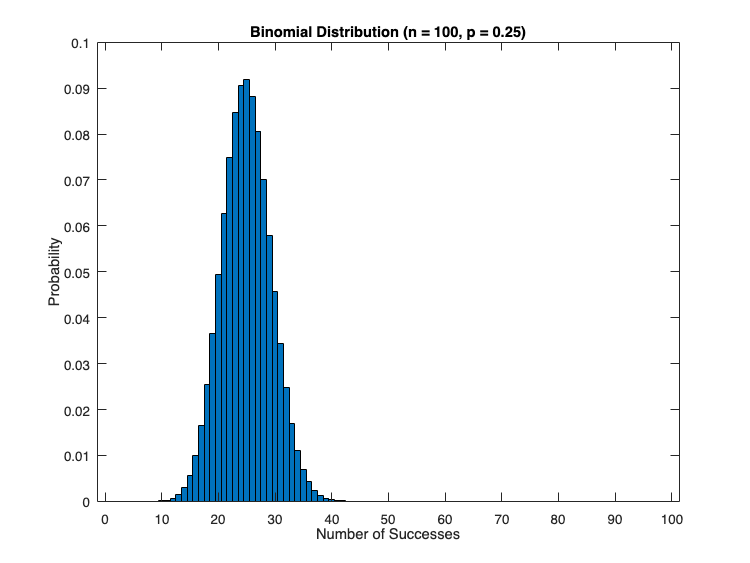

%binomial distribution

%parameters
%number of trials
n = 100;
%probability of success in a single trial
p = 1/4;

%number of successful trials, range: 0->n
x = 0:1:n;
%probability based on binomial distribution
P_bino = (factorial(n) ./ (factorial(x) .* factorial(n - x))) .* (p.^x) .* ((1 - p).^(n - x));

%plot the binomial distribution
figure
box on
bar(x, P_bino, 'BarWidth', 1, 'EdgeColor', 'k');
xlabel('Number of Successes')
ylabel('Probability')
title(['Binomial Distribution (n = ' num2str(n) ', p = ' num2str(p) ')'])

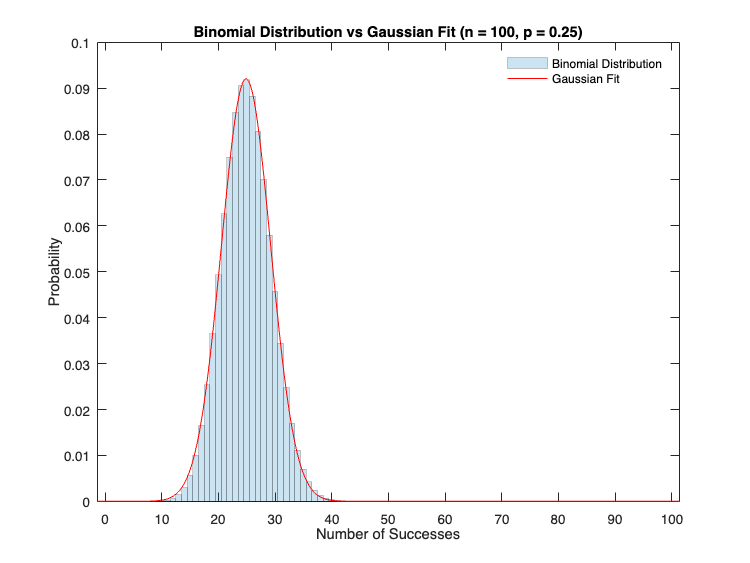

%Parameters for Binomial Distribution
n = 100; %Number of trials
p = 1/4; %Probability of success

%Compute binomial probabilities
x = 0:1:n; %number of successes (0 to n)
P_bino = binopdf(x, n, p); %Binomial distribution (use binopdf for stability)

%Clean data for fitting
valid = P_bino > 0; %Remove zero probabilities
x_fit = x(valid);                 
y_fit = P_bino(valid);

%fit Gaussian to the binomial data
f = fit(x_fit.', y_fit.', 'gauss1');  %fit a one-term Gaussian

%plot the results
figure
hold on
box on

%plot the binomial distribution as a transparent bar graph
bar(x, P_bino, 'BarWidth', 1, 'EdgeColor', 'k', 'FaceAlpha', 0.2, 'EdgeAlpha', 0.2);

%plot the fitted Gaussian curve
plot(f, 'r-');  % red Gaussian curve

%labels and title
xlabel('Number of Successes')
ylabel('Probability')
legend('Binomial Distribution', 'Gaussian Fit', 'Box', 'off');
title(['Binomial Distribution vs Gaussian Fit (n = ' num2str(n) ', p = ' num2str(p) ')'])

%binomial distribution
%mean
mean_bino = n*p;
%std
std_bino = sqrt(n*(1-p)*p);

%fitted Gaussian
coefficientValues = coeffvalues(f);
mean_gauss = coefficientValues(2);
std_gauss = coefficientValues(3)/sqrt(2);

%compare
fprintf("mean_binomial: %.1f mean_gaussian: %.1f", mean_bino, mean_gauss);

mean_binomial: 25.0 mean_gaussian: 24.9

fprintf("std_binomial: %.1f std_gaussian: %.1f", std_bino, std_gauss);

std_binomial: 4.3 std_gaussian: 4.3

fprintf('-----')

-----

fprintf('a1 = %.5f', coefficientValues(1));

a1 = 0.09202

fprintf('1/(sigma*sqrt(2*pi)) = %.5f', 1/(std_bino*sqrt(2*pi)));

1/(sigma*sqrt(2*pi)) = 0.09213

fprintf('-----')

-----

fprintf('b1 = %.5f', coefficientValues(2));

b1 = 24.87436

fprintf('mu = %.5f', mean_bino);

mu = 25.00000

fprintf('-----')

-----

fprintf('c1 = %.5f', coefficientValues(3));

c1 = 6.13378

fprintf('sqrt(2)*sigma = %.5f', sqrt(2)*std_bino);

sqrt(2)*sigma = 6.12372